# Dati laboratorio 1

## Misure


x = [100 500 1000 5000 8.8*10^3 10*10^3 50*10^3 100*10^3 500*10^3 1*10^6 5*10^6 10*10^6]; % x in frequenza

v_i_pp = [488 488 485 481 484 485 483 484 487 488 477 430].*(10^(-3)); % misura tensione picco-picco ingresso
v_o_pp = [4.802 4.799 4.779 4.188 3.388 3.163 0.833 0.427 0.943 0.542 0.621 0.106]; % misura tensione picco-picco uscita
f = [-179.3 -176.8 -173.4 -149.7 -133.9 -129.7 -96.3 -87.7 -58.6 -41.9 -35.9 -9.8]; % misura fase

## Elaborazione

x = (2*pi).*x; % x trasformata in pulsazione
x = log10(x); % poi in scala logaritmica (fatto per plot)
g = v_o_pp./v_i_pp; % calcolo guadagno circuito
g=20.*log10(g); % guadagno in dB

## Grafico modulo

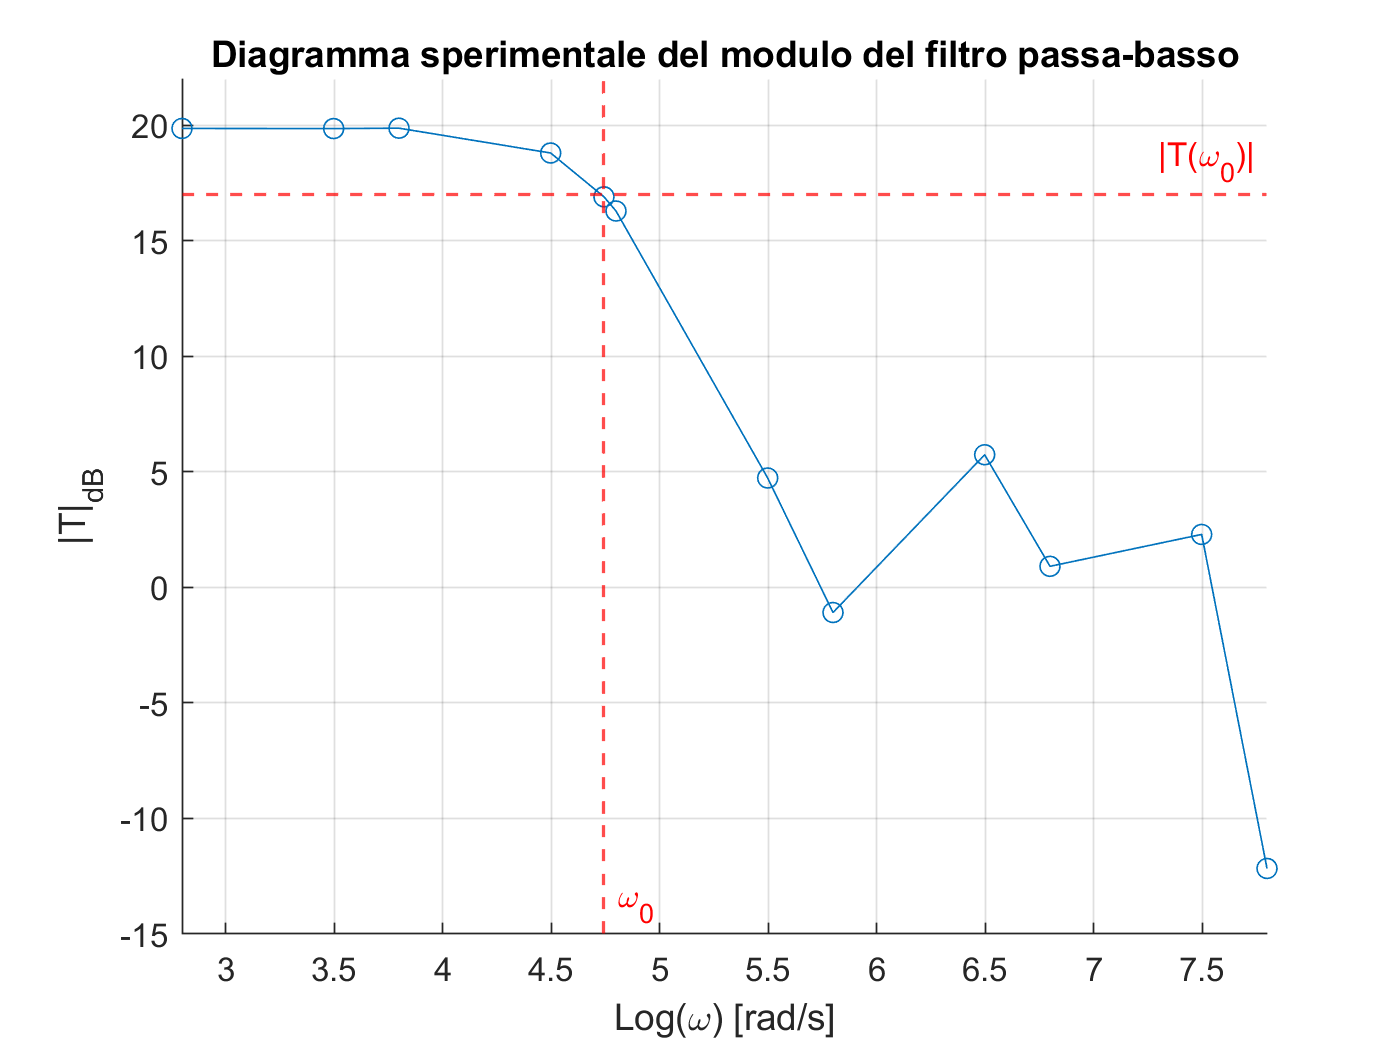

% Modulo
figure
hold on
grid on
title('Diagramma sperimentale del modulo del filtro passa-basso')
xlabel('Log(\omega) [rad/s]')
ylabel('|T|_{dB}')
axis([x(1) x(12) -15 22])
xline((x(5)),'--r','\omega_0','LabelVerticalAlignment','bottom','LabelOrientation','Horizontal','LineWidth',1)
yline(17,'--r','|T(\omega_0)|','LineWidth',1)
plot(x,g,'-o')
% Cambiare con il percorso in cui si ha la cartella immagini della relazione
saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S1\LabElettronica\Relazioni-Lab-Elettronica\Relazione 1\TexFiles\immagini\modulo_sper.png');
% saveas(gcf,'C:\Users\Martina\Documents\UNIBG\2022-23\PRIMO SEMESTRE\Laboratorio di elettronica\Relazioni-Lab-Elettronica\Relazione 1\TexFiles\immagini\modulo_sper.png');

## Grafico fase

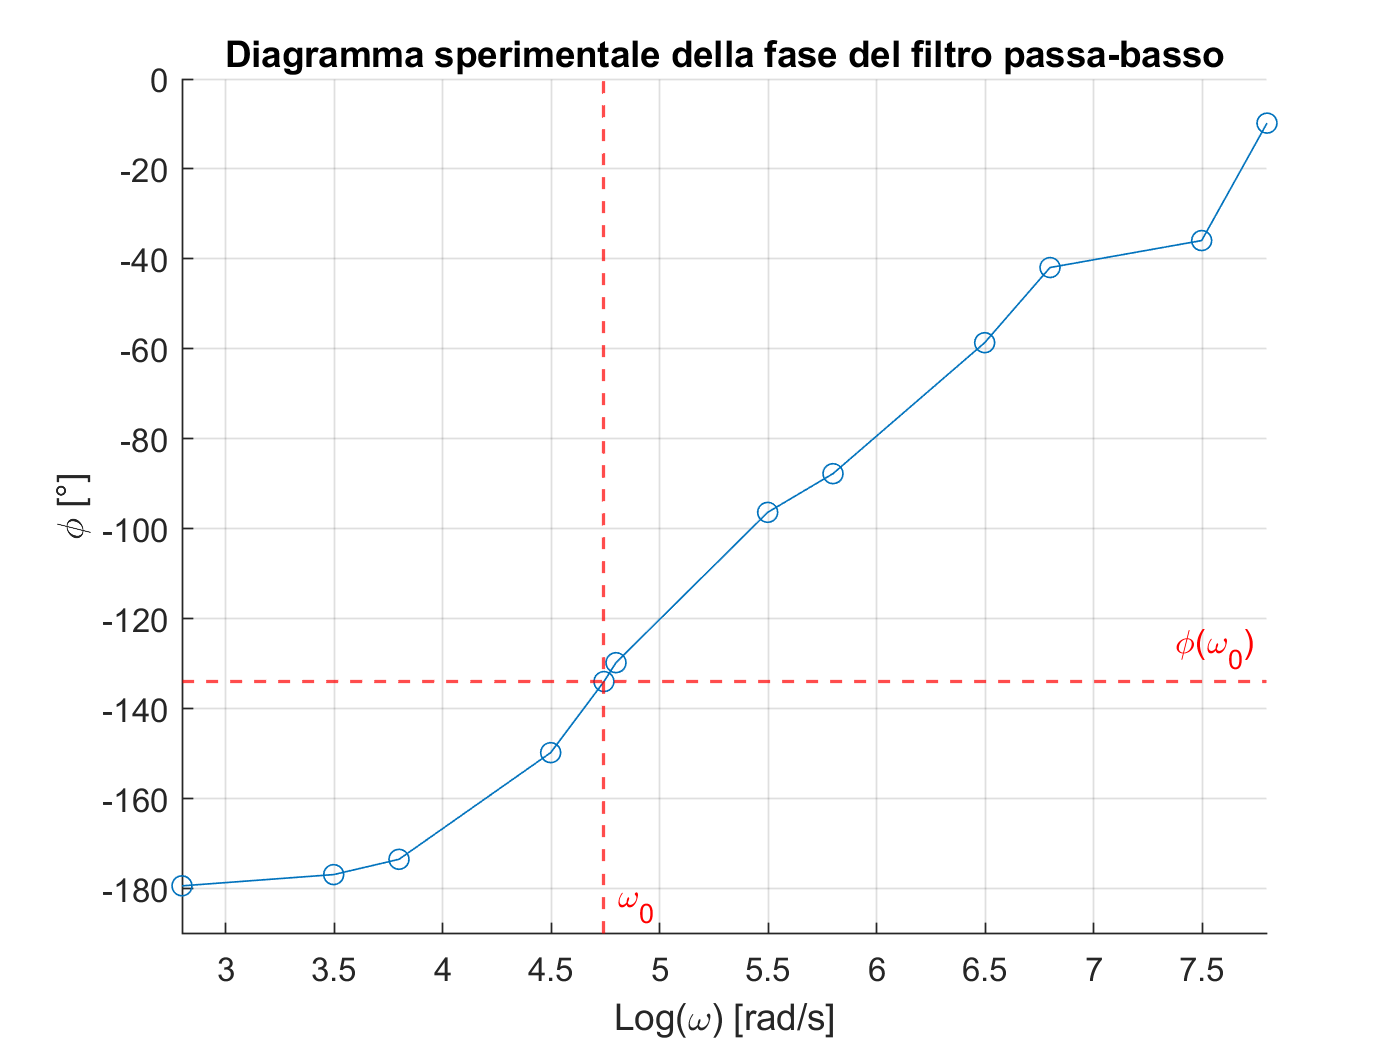

figure
hold on
grid on
title('Diagramma sperimentale della fase del filtro passa-basso')
xlabel('Log(\omega) [rad/s]')
ylabel('\phi [°]')
axis([x(1) x(12) -190 0])
xline((x(5)),'--r','\omega_0','LabelVerticalAlignment','bottom','LabelOrientation','Horizontal','LineWidth',1)
yline(-134,'--r','\phi(\omega_0)','LineWidth',1)
plot(x,f,'-o')
% Cambia con il percorso in cui hai la cartella immagini della relazione
saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S1\LabElettronica\Relazioni-Lab-Elettronica\Relazione 1\TexFiles\immagini\fase_sper.png');
% saveas(gcf,'C:\Users\Martina\Documents\UNIBG\2022-23\PRIMO SEMESTRE\Laboratorio di elettronica\Relazioni-Lab-Elettronica\Relazione 1\TexFiles\immagini\fase_sper.png');

## Diagrammi di Bode teorici

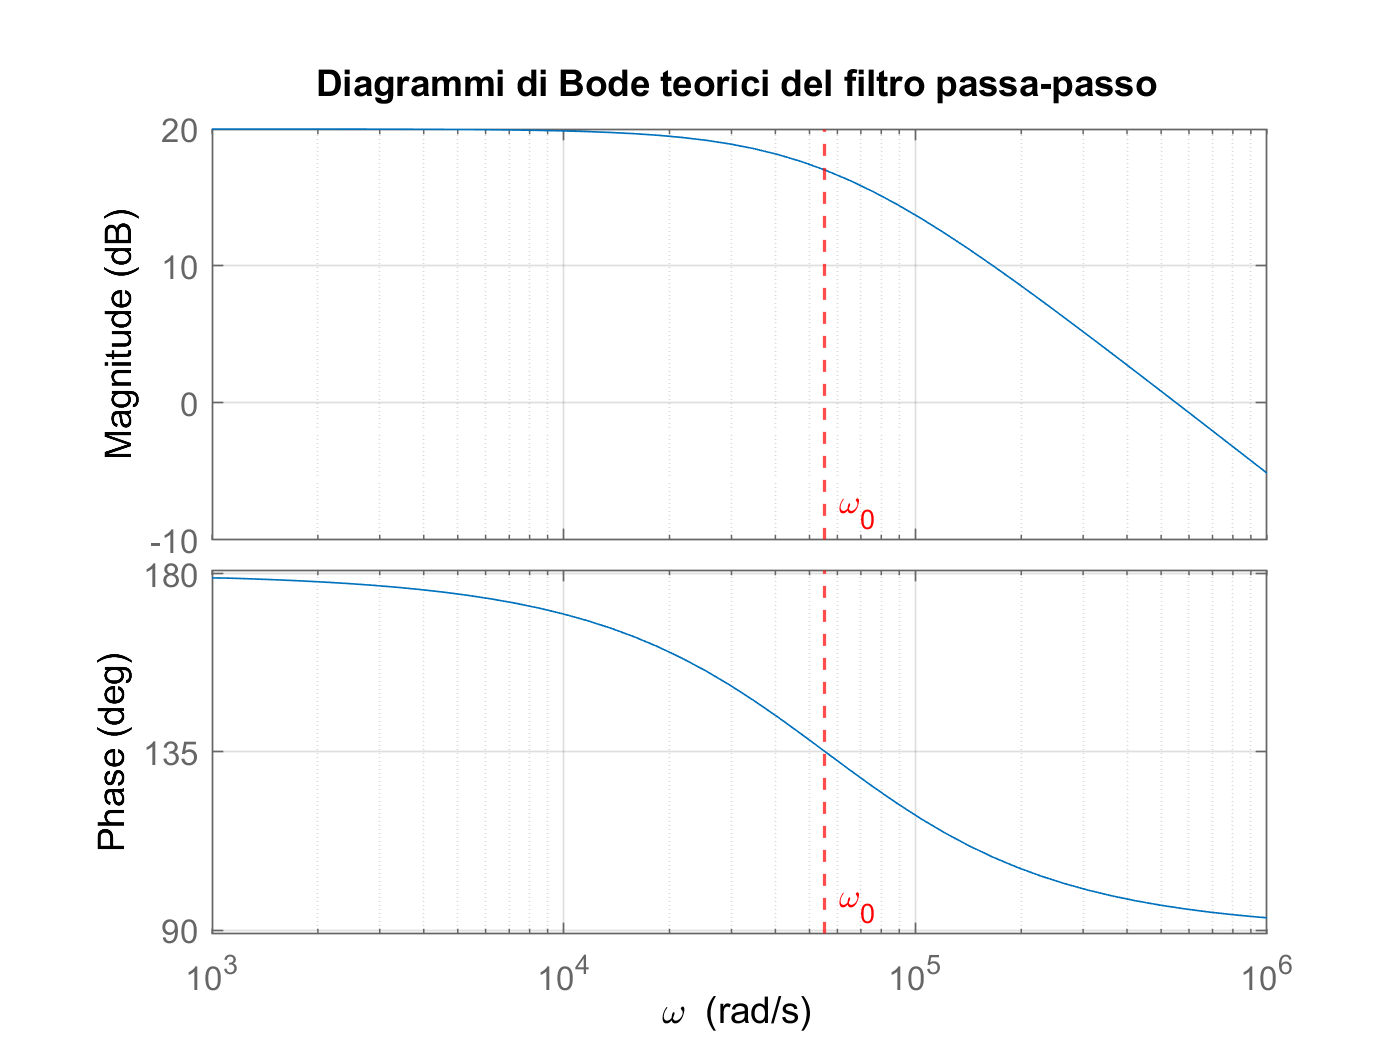

% Parametri circuito
R1 = 18*10^3;
R2 = 1.8*10^3;
C1 = 10^(-9);
fdt = tf([0 (-R1/R2)],[(R1*C1) 1]);
% Grafici
figure
xline((2*pi*8.8*10^3),'--r','\omega_0','LabelVerticalAlignment','bottom','LabelOrientation','Horizontal','LineWidth',1)
hold on
bodeplot(fdt)
grid on
xline((2*pi*8.8*10^3),'--r','\omega_0','LabelVerticalAlignment','bottom','LabelOrientation','Horizontal','LineWidth',1)
title('Diagrammi di Bode teorici del filtro passa-passo')
xlabel('\omega')
% Cambia con il percorso in cui hai la cartella immagini della relazione
saveas(gcf,'C:\Users\giuly\Desktop\università\ANNO 5\S1\LabElettronica\Relazioni-Lab-Elettronica\Relazione 1\TexFiles\immagini\Bode_teo.png');
% saveas(gcf,'C:\Users\Martina\Documents\UNIBG\2022-23\PRIMO SEMESTRE\Laboratorio di elettronica\Relazioni-Lab-Elettronica\Relazione 1\TexFiles\immagini\Bode_teo.png');